# Monte Carlo Method for Radioactive Decay

## variables

N0 = 100;           % initial number of nuclei
N=zeros(1,N0);      % create vector to store decaying nuclei
timestep = 30;      % days
lambda = 3.6*10^-4;  % decay constant
nucleiN = 1:100;    % used to plot nuclei
p = lambda*timestep; % probability of decay
time=0:timestep:100000; %exact time
Nundecayed=zeros(1,N0); %number of undecayed nuclei
index=0;

## method

for t = 0:timestep:100000
    for i = 1:N0
        r = rand;  
        if r < p && N(i)~= 1
            N(i) = 1;
            %plot(nucleiN,N,'bo');
            %pause
        end
    end
    index=index+1;
    Nundecayed(index)=100-sum(N);
end

## plot

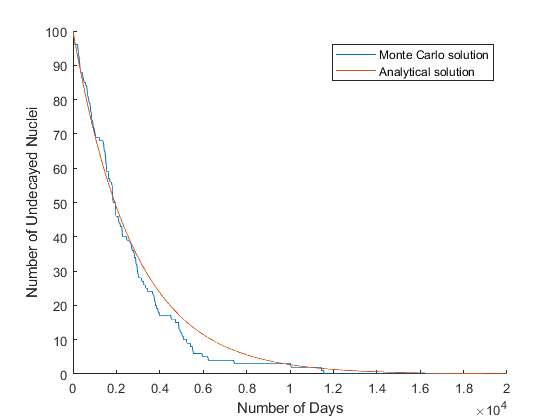

hold on
ExactSol=N0.*exp(-lambda.*time);
plot(time, Nundecayed);
plot(time,ExactSol);
xlim([0 2*10^4]);
xlabel('Number of Days');
ylabel('Number of Undecayed Nuclei');
legend('Monte Carlo solution','Analytical solution');